## project2.mlx, Leo Berman & Justin Ok, 10/5/2023

# Signals Project 2

Leo Berman & Justin Ok

## Symming s, t, setting input as impulse to find transfer function

clear all
close all
clc
syms s t
vx = dirac(t);

## Finding minimum spring constant to hold a human being

m_human = 28.8+22+26.35+6.76;
g = 9.8; % m/s^2 gravitational constant
weight_human = m_human*g;
x = .02; % setting the displacement to a couple of centimeters for a firm chair
spring_constant = weight_human/x;

spring_constant = 4.1116e+04

## Physical properties of the human/chair combo

b = 90;
k = 3500;
m1 = 50; % chair weight kg
k1 = spring_constant; % spring constant of chair
b1 = 5; % damping constant of chair
m2 = 28.8; % lower torso kg
k2 = k; % spring constant of bones
b2 = b; % damping constant of soft tissue
m3 = 22; % middle torso kg
k3 = k; % spring constant of bones
b3 = b; % damping constant of soft tissue
m4 = 26.35; % upper torso kg
k4 = k; % spring constant of bones
b4 = b; % damping constant of soft tissue
m5 = 6.76; % head weight kg

## Circuit conversion into s domain

ZC1 = 1/(s*m1);
ZL1 = s/k1;
ZR1 = 1/b1;
ZC2 = 1/(s*m2);
ZL2 = s/k2;
ZR2 = 1/b2;
ZC3 = 1/(s*m3);
ZL3 = s/k3;
ZR3 = 1/b3;
ZC4 = 1/(s*m4);
ZL4 = s/k4;
ZR4 = 1/b4;
ZC5 = 1/(s*m5);
ZRL1 = (1/ZR1 + 1/ZL1)^-1;
ZRL2 = (1/ZR2 + 1/ZL2)^-1;
ZRL3 = (1/ZR3 + 1/ZL3)^-1;
ZRL4 = (1/ZR4 + 1/ZL4)^-1;

## Nodal

syms I1 I2 I3 I4 I5 I6 I7 I8 I9
eq1 = I1 == I2 + I3;
eq2 = I2 == I4 + I5;
eq3 = I4 == I6 + I7;
eq4 = I6 == I8 + I9;

Vx = laplace(vx);
syms V1 V2 V3 V4
eq5 = I1 == (Vx-V1)/ZRL1;
eq6 = I2 == (V1-V2)/ZRL2;
eq7 = I3 == V1/ZC2;
eq8 = I4 == (V2-V3)/ZRL3;
eq9 = I5 == V2/ZC3;
eq10 = I6 == (V3-V4)/ZRL4;
eq11 = I7 == V3/ZC4;
eq12 = I8 == 0;
eq13 = I9 == V4/ZC5;

eqns = [eq1 eq2 eq3 eq4 eq5 eq6 eq7 eq8 eq9 eq10 eq11 eq12 eq13];
vars = [I1 I2 I3 I4 I5 I6 I7 I8 I9 V1 V2 V3 V4];
sol = solve(eqns,vars);
Hs = partfrac(sol.V4);

## Response to u(t)-u(t-1) going up a curb

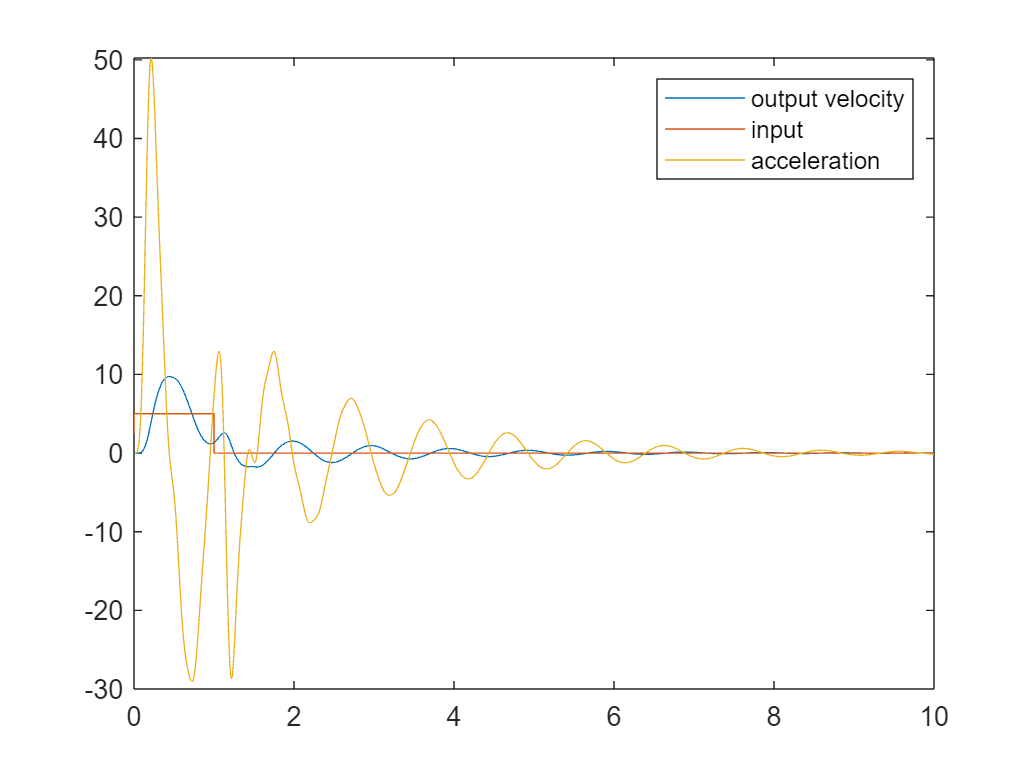

invsout(Hs,(heaviside(t)-heaviside(t-1)))

## Trying to get the response via laplaces

function[maxaccel]=invsout(transfunc,input)
    syms t s
    in = 5*input;
    out = ilaplace(transfunc*laplace(in))*heaviside(t);
    accel = diff(out);
    fplot(out,[0 10]);
    hold on;
    fplot(in,[0 10]);
    hold on;
    fplot(accel,[0 10]);
    hold on;
    legend('output velocity', 'input','acceleration');
    hold off;
    afunc = @(t) accel;
    %maxaccel = findpeaks(afunc)
    %maxaccel = max(afunc)
    %afuncsampls = real(afunc([0 1]));
    %maxaccel = max(afuncsampls);
end
